# Code for assessing local tuning biases in the mouse dLGN

- perhaps add something that is not the title of your paper, maybe the goal of the paper, or the significance sttament

- link abstract or complete manuscript/thesis

## Goals, Hypothesis and Analysis

The aim of the project is to assess the presence of 'local tuning biases' among populations of LGN afferents innervating the mouse primary visual cortex. 

Put simply, we test the notion that groups of LGN neurons  'processing' signals from the same region of visual space do so with a biased set of orientated filters. 

To answer this questoin,  

- we Estimate the linear spatial receptive field maps and joint orientation tuning X spatial frequency tuning of populations of thalamic boutons that innervating mouse V1. 

- then For each pair of boutons in the population, find the overlap between the receptive fields the and the similarity of their tuning profiles

- If LGN boutons with overlapping receptive fields have similar tuning profiles, this would suggest the presence of local tuning biases.

# Prepare Data Files

clear;
clc;
cd /Users/luis/Box/prjLGNTB/
addpath /Users/luis/Box/prjLGNTB/lgnDATA/   
addpath /Users/luis/Box/prjLGNTB/lgnANALYSIS/

lgn = lgnanz;
lgn.uif_tbl_base

ans = 11×4 table
    uif    mouse_id      fname_base_ret      fname_base_orisf 
    ___    _________    _________________    _________________
     1     {'lgn02'}    {'lgn02_000_004'}    {'lgn02_000_003'}
     2     {'lgn02'}    {'lgn02_001_000'}    {'lgn02_001_001'}
     3     {'lgn02'}    {'lgn02_002_000'}    {'lgn02_002_002'}
     4     {'lgn02'}    {'lgn02_003_000'}    {'lgn02_003_001'}
     5     {'lgn03'}    {'lgn03_001_001'}    {'lgn03_001_000'}
     6     {'lgn03'}    {'lgn03_001_003'}    {'lgn03_001_002'}
     7     {'lgn03'}    {'lgn03_002_001'}    {'lgn03_002_000'}
     8     {'lgn04'}    {'lgn04_002_000'}    {'lgn04_002_003'}
     9     {'lgn05'}    {'lgn05_001_001'}    {'lgn05_001_000'}
    10     {'lgn05'}    {'lgn05_008_001'}    {'lgn05_008_000'}
    11     {'lgn05'}    {'lgn05_011_000'}    {'lgn05_011_001'}

these are all the unique  fields that were imaged. 9 total imaging sessions were conducted, from 4 different mice.

# Assessing properties of LGN Boutons

## Load the 'roi' (LGN bouton) data table 

discuss implications 

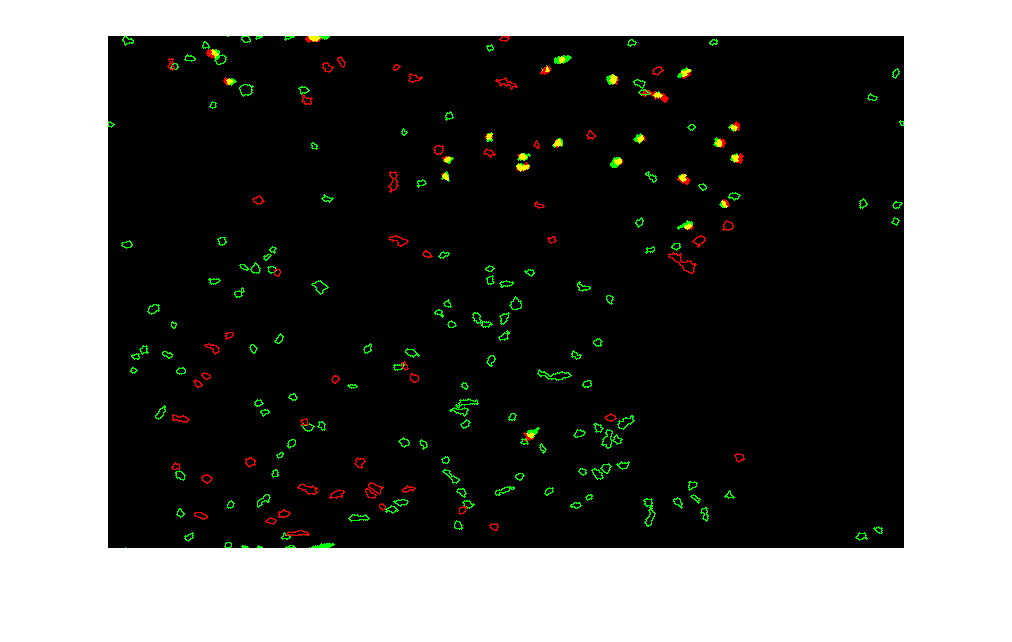

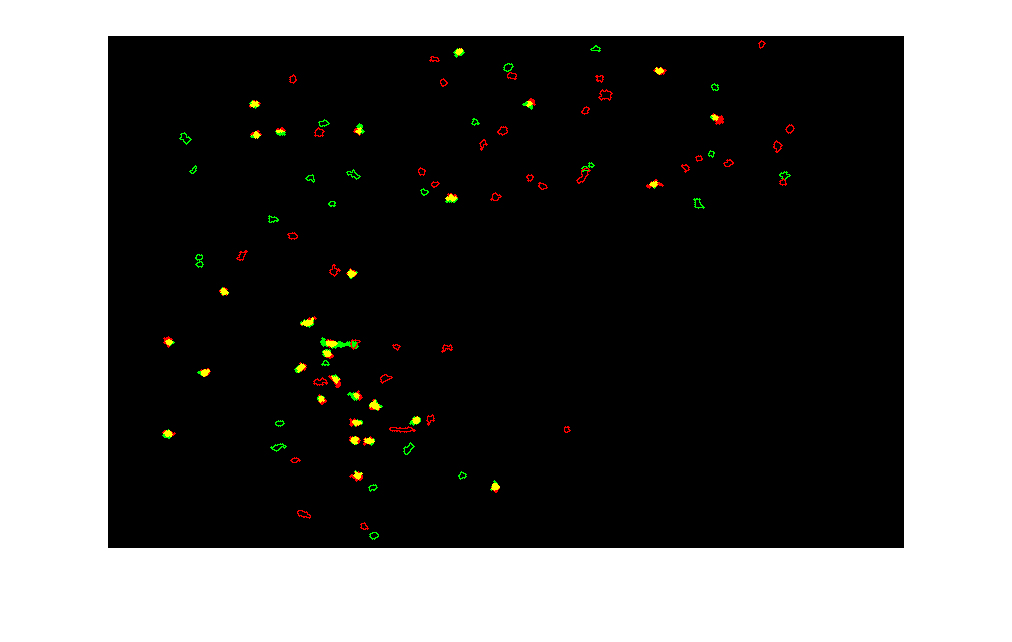

uifs_to_process = [3 4];
lgn.get_roi_tables(uifs_to_process);


lgn.roi_stack_uif_list; % here are all the imaging fields in the roi table
head(lgn.roi_stack) 

ans = 8×22 table
    masterEntry    entryNumber      mouse      uniqImFieldNum    hasRetData    hasTunData    roi_ID_Ret    roi_ID_Tun        kern_ret         kurt_ret        sig_ret            xy_ret       kern_tun    signif_tun    sig_tun      oricurve       oriest       sfcurve       osi    sfPeak    segment_xy_tun    segment_area_tun
    ___________    ___________    _________    ______________    __________    __________    __________    __________    _________________

tail(lgn.roi_stack)

ans = 8×22 table
    masterEntry    entryNumber      mouse      uniqImFieldNum    hasRetData    hasTunData    roi_ID_Ret    roi_ID_Tun        kern_ret         kurt_ret        sig_ret            xy_ret          kern_tun       signif_tun        sig_tun           oricurve            oriest            sfcurve              osi                  sfPeak                     segment_xy_tun               segment_area_tun
    ___________    ___________    _________    ______________    __________    __________    _________

Now you have a table of rois 

- rows correspond to a lgn bouton in some imaging field

- columns correspond some property of those boutons. These properties include: imaging field ID, tuning kernel, retinotpoic kernel, orientation preference, spatial frequency preference, etc

- note that some rois have both tuning kernels AND receptive fields, while some have only one but not the other. This analysis only considers boutons with BOTH types of kernels

## Tuning preferences and other properties of LGN boutons

% add code here

## Discussion

# Test whether populations of LGN boutons exhibit local tuning biases

## Generate a bouton-pair 'distance' data table

lgn.get_distance_table(); 
head(lgn.dist_stack)    
tail(lgn.dist_stack)

Now you have a distance table

- rows correspond to some pair of LGN boutons in some imaging field

- columns correspond some property of that bouton pair (retinotopic overlap, similarity of tuning kernel, etc)

## Model the relationship between tuning similarity and RF overlap, for pairs of boutons in one imaging field

Fit a linear Model and Run a Rank sum test for one population of LGN boutons

% figure(1)
clf;


ans = 8×33 table
      mouse      uif    pair_roiDistMatIdx    pair_roiOrisfId    pair_roiHoughId    dRetKern_c2cDist    dRetKern_corr    dRetKern_corrStrong    dRetKern_corrWeak     dRetKern_Overlap     dRetKern_OverlapFiftyPrc    dRetKern_OverlapYes    dRetKern_OverlapNo      dTunKern_cos         dTunKern_corr            dSfResp              dLogSfEst         dLogSfEst_lessThanHalfOct    dLogSfEst_lessThanOneOct    dLogSfEst_lessThanTwoOct    dLogSfEst_lessThanThreeOct    dLogSfEst_AnyDiff    dLogSfEst_moreThanHalfOct    dLogSfEst_moreThanOneOct    dLogSfEst_moreThanTwoOct

uif  = lgn.roi_stack_uif_list(1);

ans = 8×33 table
      mouse      uif    pair_roiDistMatIdx    pair_roiOrisfId    pair_roiHoughId    dRetKern_c2cDist     dRetKern_corr    dRetKern_corrStrong    dRetKern_corrWeak     dRetKern_Overlap     dRetKern_OverlapFiftyPrc    dRetKern_OverlapYes    dRetKern_OverlapNo      dTunKern_cos         dTunKern_corr            dSfResp              dLogSfEst         dLogSfEst_lessThanHalfOct    dLogSfEst_lessThanOneOct    dLogSfEst_lessThanTwoOct    dLogSfEst_lessThanThreeOct    dLogSfEst_AnyDiff    dLogSfEst_moreThanHalfOct    dLogSfEst_moreThanOneOct    dLogSfEst_moreThanTwoOct</

lgn.fit_plot_lm(uif);


Run it again but this time with the entire data set, accross all imaging

uif_stack   = lgn.roi_stack_uif_list;
lgn.fit_plot_lm(uif_stack);

## Discussion